# Test the Model

## Read in optimised hyperparameters

LSTMCNN

optVars = load("HyperParameterSearch\OptVars\LSTMCNNoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numLSTMBlocks = optVars.numLSTMBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numCNNBlocks = optVars.numCNNBlocks;
filterSize = optVars.filterSize;
numFilters = optVars.numFilters;

biLSTM

optVars = load("HyperParameterSearch\OptVars\biLSTMoptVars.mat").optVars;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
numFeatures = 3;
numBlocks = optVars.numBlocks;
numHiddenUnits = optVars.numHiddenUnits;
numResponse = 3;

TCN

optVars = load("HyperParameterSearch\OptVars\TCNoptVars.mat").optVars;
numFilters = optVars.numFilters;
filterSize = optVars.filterSize;
numBlocks = optVars.numBlocks;
dropoutFactor = optVars.dropoutFactor;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;

CNN1d

optVars = load("HyperParameterSearch\OptVars\CNN1doptVars.mat").optVars;
numFilters = optVars.numFilters;
filterSize = optVars.filterSize;
numBlocks = optVars.numBlocks;
miniBatchSize = optVars.miniBatchSize;
learningrate = optVars.learningrate;
poolSize = optVars.poolSize;

WTCNN

optVars = load("HyperParameterSearch\OptVars\WTCNNoptVars.mat").optVars;
imSize=size(imread('DataSet\HyperparameterSearch\Train\Img\WTImg\0001_wt.jpg'));
numBlocks = optVars.numBlocks;
filterSizeC= floor((optVars.filterSizeC)/2)*2+1;
filterSizeS= floor((optVars.filterSizeS)/2)*2+1;
numFilter= optVars.filterNum;
dropoutLayerRegularization = optVars.dropoutLayerRegularization;
learningrate = optVars.learningrate;
activation=optVars.activation;
miniBatchSize=optVars.batchSize;
classes = ["blink","noBlink", "muscleArtifact"];

## Test the model several times

rng(1);
numTesting = 10;
Maxepochs = 30;

LSTMCNN

modelName = 'LSTMCNN';
accuracy = {};
confusionmats = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    numResponse = numel(categories(YTest{1}));
    numFeatures = size(XTrain{1},1);
    layers = constructLSTMCNN(numFeatures,numLSTMBlocks,numHiddenUnits, ...
        numCNNBlocks,filterSize,numFilters,numResponse,false); 
    % train
    options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    confusionmats{end+1} = confusionMat;
end

result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

LSTM

modelName = 'LSTM';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructLSTM(numFeatures,numBlocks,numHiddenUnits,numResponse,false); 

    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

biLSTM

modelName = 'biLSTM';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructLSTM(numFeatures,numBlocks,numHiddenUnits,numResponse,false); 

    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

TCN

modelName = 'TCN';
accuracy = {};
confusionmats = {};
pred = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    layers = constructTCN(size(XTrain{1}, 1), numFilters, filterSize, numBlocks, dropoutFactor);

    options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    
    
    net = trainNetwork(XTrain,YTrain,layers,options);

    
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
        valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    pred{end+1} = YPred; 
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end
result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');
save(['Test\Results\' modelName 'pred.mat'],'pred','-mat');

CNN1d

modelName = 'CNN1d';
accuracy = {};
confusionmats = {};
for i = 1:numTesting
    % load data set
    XTrain = load(['DataSet\Test\Train\XTestTrain' num2str(i) '.mat']).XTestTrain;
    YTrain = load(['DataSet\Test\Train\YTestTrain' num2str(i) '.mat']).YTestTrain;
    XTest = load(['DataSet\Test\Test\XTestTest' num2str(i) '.mat']).XTestTest;
    YTest = load(['DataSet\Test\Test\YTestTest' num2str(i) '.mat']).YTestTest;    
    % model
    numResponse = numel(categories(YTest{1}));
    numFeatures = size(XTrain{1},1);
    layers = constructCNN(size(XTrain{1}, 1), numBlocks, filterSize, numFilters,poolSize, 3);

        options = trainingOptions('adam', ...
            'MaxEpochs',Maxepochs, ...
            'MiniBatchSize',miniBatchSize, ...
            'InitialLearnRate',learningrate, ...
            'LearnRateDropPeriod',10, ...
            'LearnRateDropFactor',0.75, ...
            'LearnRateSchedule','piecewise', ...
            'Plots','none',...
            'GradientThreshold',1, ...
            'shuffle','every-epoch',...
            'Verbose',0,...
            'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy{end+1} = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end
    confusionMat = confusionmat(TY(:),Y(:));
    confusionmats{end+1} = confusionMat;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
end

result = table(accuracy, confusionmats);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

WTCNN

     1

     2



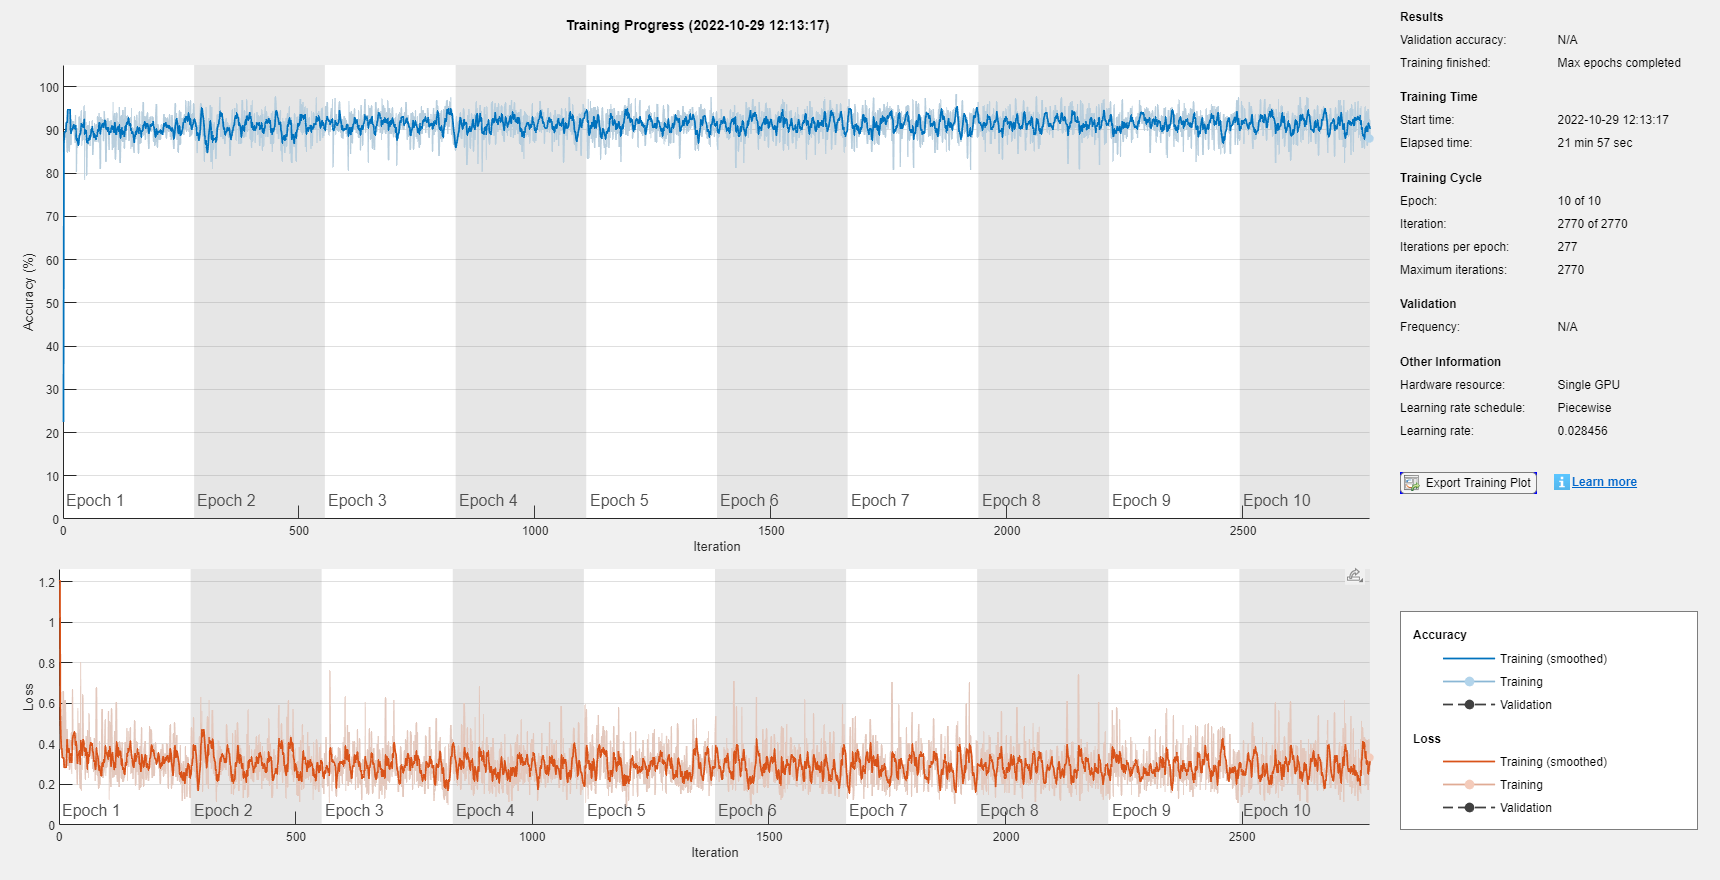

     3



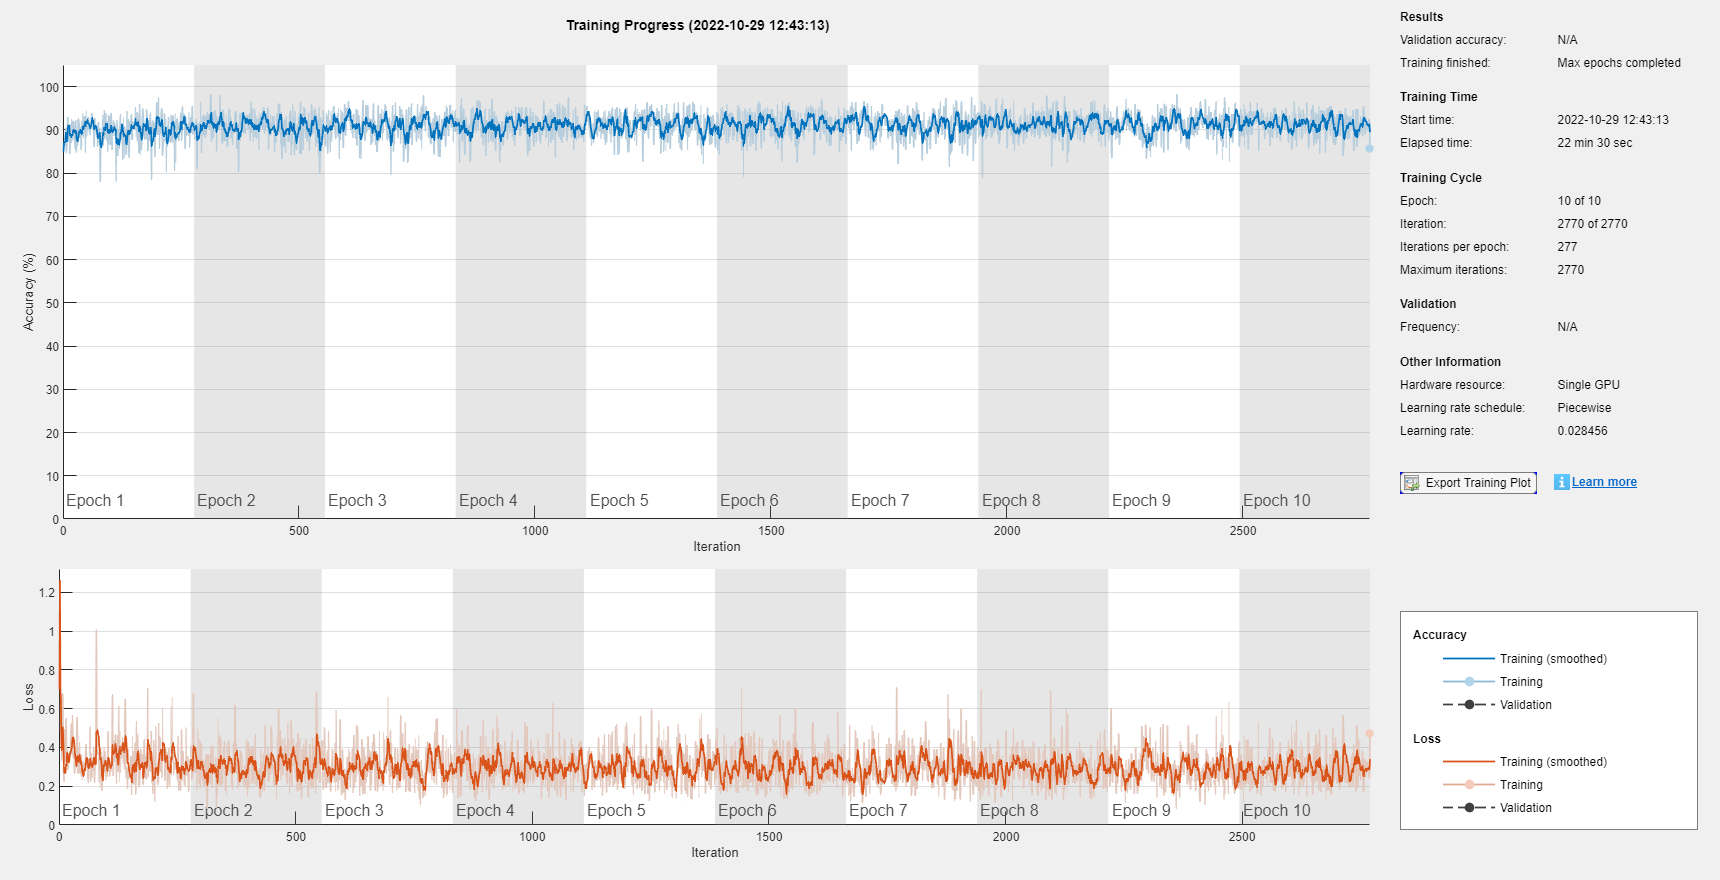

     4

     5

     6

     7

     8



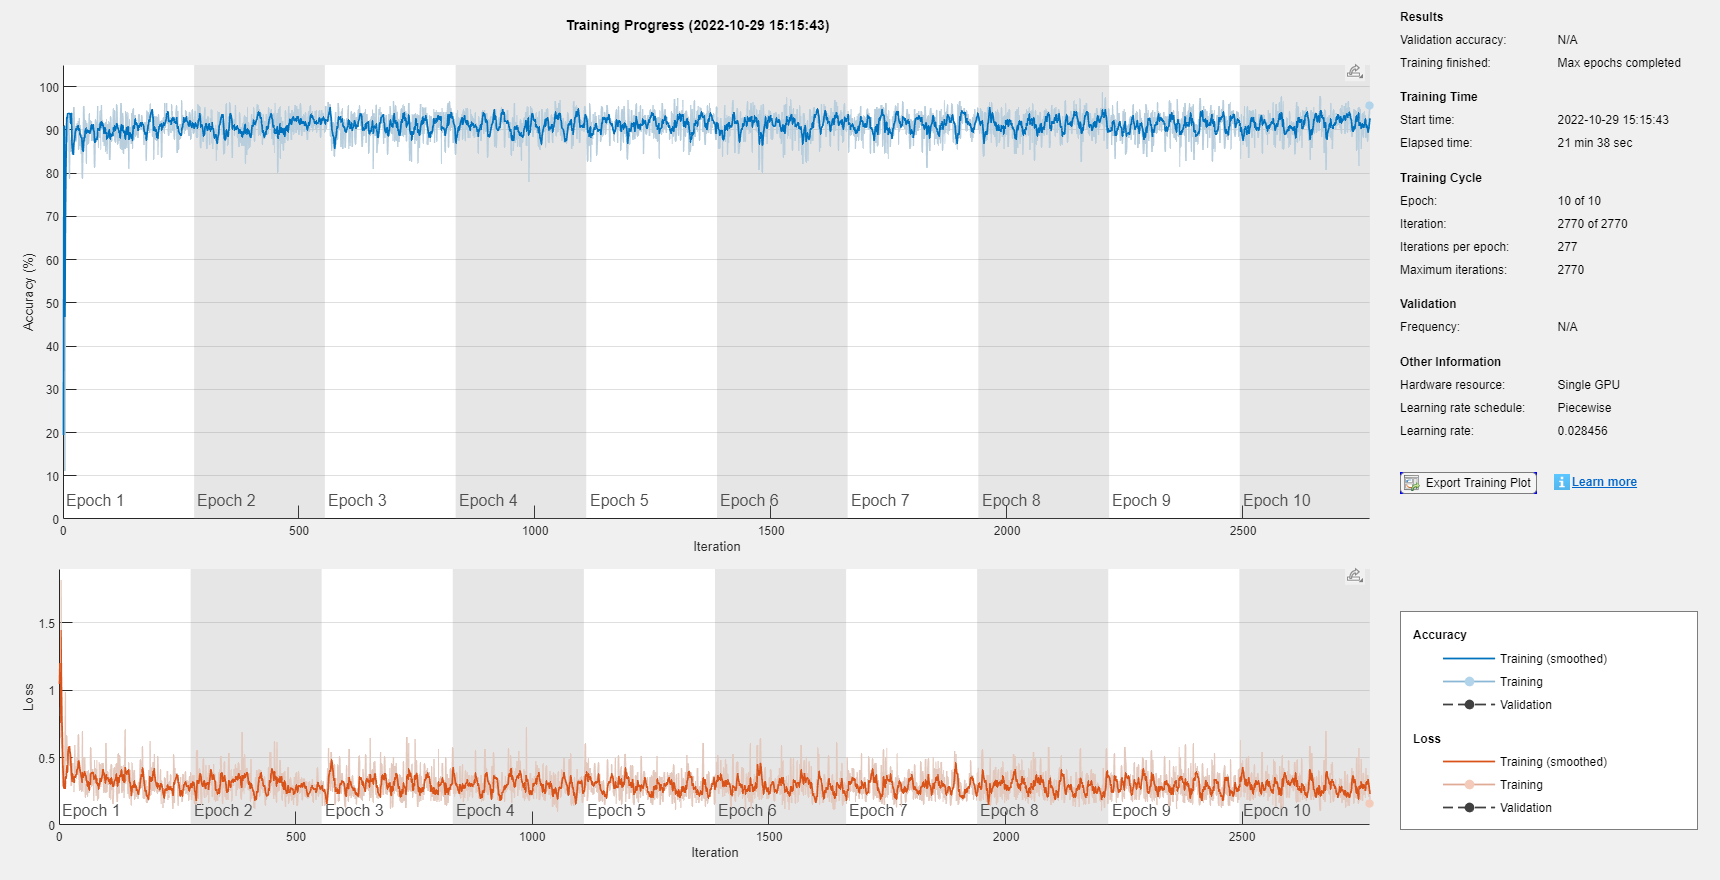

     9



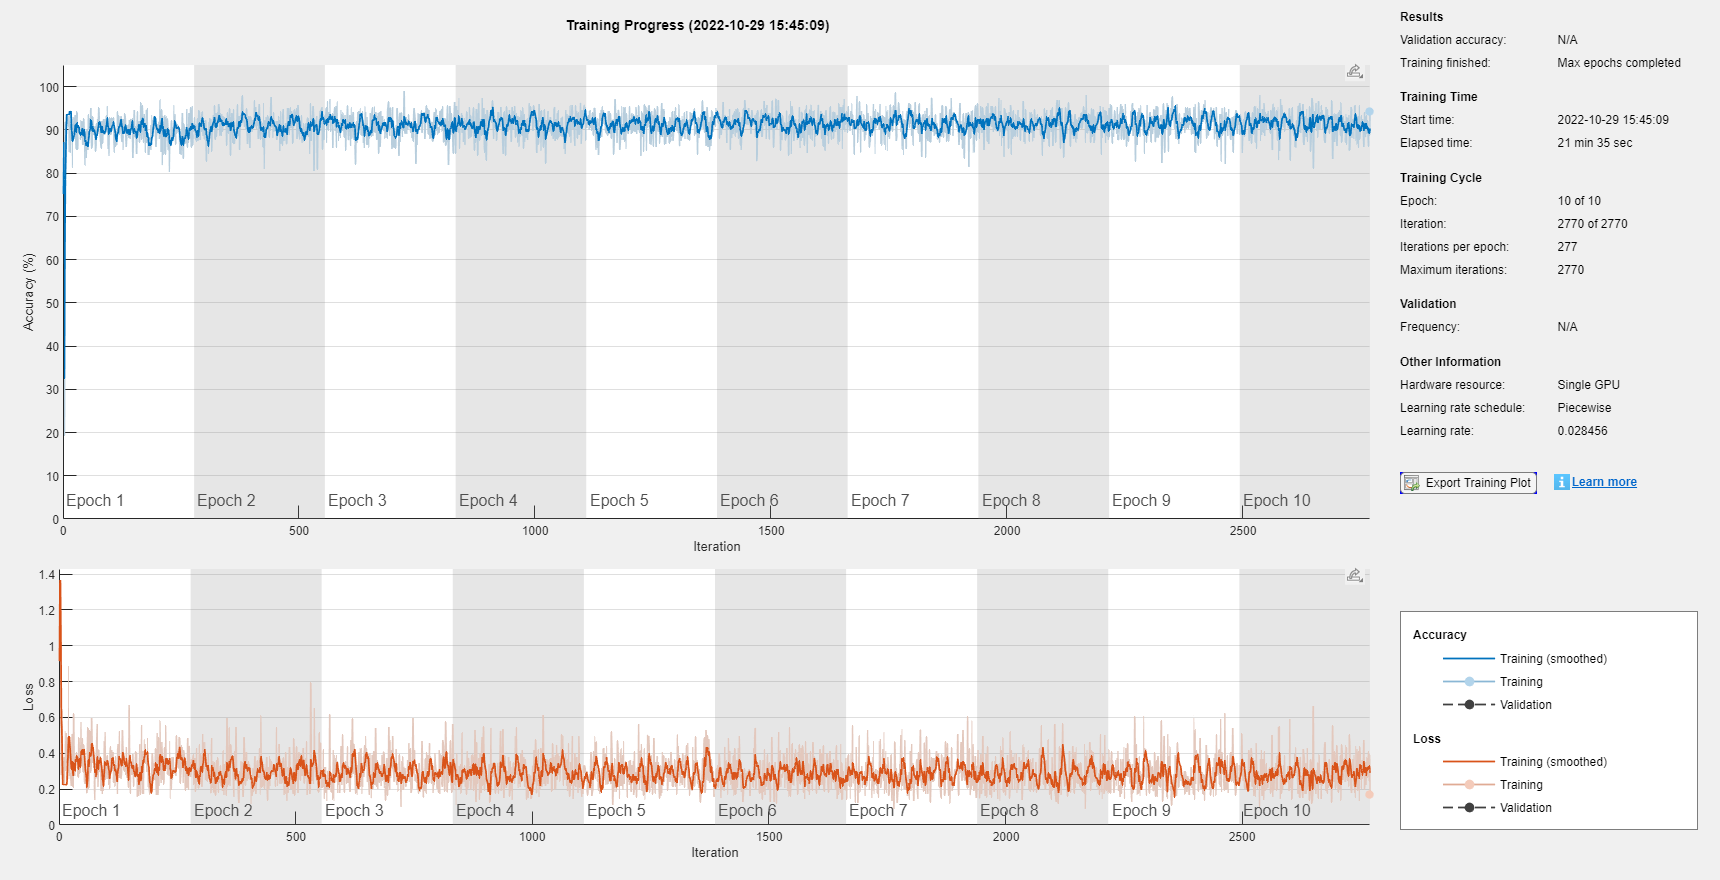

    10



modelName = 'WTCNN';
accuracy = {};
predResult = {};
learningrate = learningrate/3;
for i = 1:10%numTesting
    % load data set
    YLable = load(fullfile('DataSet','Test','Test',['YTestTest' num2str(i) '.mat'])).YTestTest;
    imdsTest = imageDatastore(fullfile('DataSet','Test','Test',['Img', num2str(i)],'WTImg'),FileExtensions=".jpg");
    testImgSize = [size(imread(imdsTest.Files{1,1})) 1 1];
    imgsTest = ones(testImgSize);
    for k =1:numel(imdsTest.Files)
        imgsTest = cat(4,imgsTest,reshape(imread(imdsTest.Files{k,1}), testImgSize));
    end
    imgsTest=imgsTest(:,:,:,2:end);
    
        % load data set
    YLable = load(fullfile('DataSet','Test','Test',['YTestTest' num2str(i) '.mat'])).YTestTest;
    TY = YLable{1};
    for k = 2:numel(YLable)
    TY = [TY;YLable{k}];
    end
    dsTest = {TY,imgsTest};

    YLable = load(fullfile('DataSet','HyperparameterSearch','Test','YSearchTest.mat')).YSearchTest;
    dataClassNames = ["blink","n/a", "muscle-artifact"];pixelLabelIds = 1:numel(dataClassNames);
    classNames=["blink","noBlink", "muscleArtifact"];
    imdsTrain = imageDatastore(['DataSet\Test\Train\Img' num2str(i) '\WTImg'],FileExtensions=".jpg");
    pxdsTrain = pixelLabelDatastore(['DataSet\Test\Train\Img' num2str(i) '\PLImg'],classNames,pixelLabelIds);
    
    imdsTest = imageDatastore(['DataSet\Test\Test\Img' num2str(i) '\WTImg'],FileExtensions=".jpg");
    pxdsTest = pixelLabelDatastore(['DataSet\Test\Test\Img' num2str(i) '\PLImg'],classNames,pixelLabelIds);
    
    dsTrain = combine(imdsTrain,pxdsTrain);

    imSize=size(imread('DataSet\HyperparameterSearch\Train\Img\WTImg\0001_wt.jpg'));
    layers = simpleCNNpixel(imSize,numBlocks,filterSizeC,filterSizeS+4, ...
    numFilter, dropoutLayerRegularization,classes,activation); 
    % train
    options = trainingOptions('adam', ...
        'MaxEpochs',30, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(dsTrain,layers,options);
    % evaluate
    [YPred,scores,allScores]=semanticseg(imgsTest,net);
    valError = 1-mean(YPred == TY','all');
    accuracy{end+1} = valError;
    predResult{end+1} = YPred;
    if i == 1
        save(['Models\trainedModels\' modelName 'net.mat'],'net','-mat');
    end
    disp(i);

end


result = table(accuracy, predResult);
save(['Test\Results\' modelName 'result.mat'],'result','-mat');

## Standard deviation of accuracy

modelName = 'WTCNN';
accuracyList = [];
accuracy = load(['Test\Results\' modelName 'result.mat']).result.accuracy;
for i = 1:numTesting
    accuracyList = [accuracyList, accuracy{i}];
end
accuracyMean = mean(accuracyList),accuracyStd = std(accuracyList)

accuracyMean = 0.9535

accuracyStd = 0.0071


figure;
confusionchart(load(['Test\Results\' modelName 'result.mat']).result.confusionmats{1}, ...
    {'blink' 'n/a' 'muscle-artifact'},'Normalization','column-normalized','RowSummary','row-normalized');

Error using indexing
Unrecognized table variable name 'confusionmats'.

## Blink detect accuracy

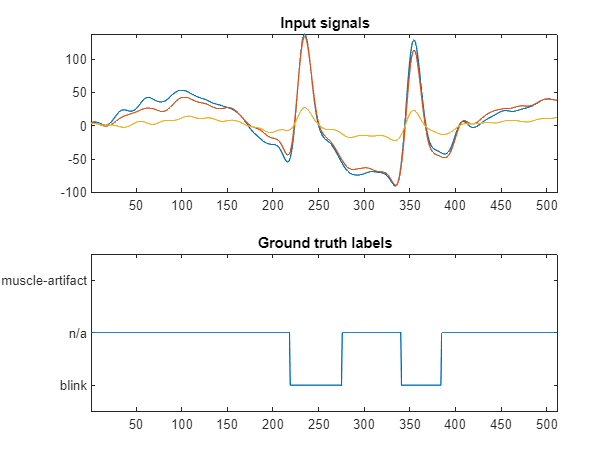

i = 1;
% i=errorList(2);
Ypred = YPred{i};
Ytest = YTest{i};
Xtest = XTest{i};
Xdif = diff(Xtest')';

figure;

subplot(2,1,1);plot(Xtest');xlim([1 512])
title("Input signals")

% subplot(4,1,2);plot(Xdif');xlim([1 512])
% title("Differential signals")

subplot(2,1,2);plot(Ytest);xlim([1 512])
title("Ground truth labels")


% subplot(4,1,4);plot(Ypred);xlim([1 512])
% title("Predict labels")

OC Pred

XTrain = load('DataSet\OpeningClosing\XTrain.mat').XTrain;
YTrain = load('DataSet\OpeningClosing\YTrain.mat').YTrain;
XTest = load('DataSet\OpeningClosing\XTest.mat').XTest;
YTest = load('DataSet\OpeningClosing\YTest.mat').YTest;
net = load('Models\trainedModels\TCNOCnet.mat').net;
YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
% blinkLocate(Xtest,Ytest),blinkLocate(Xtest,Ypred)YTest
valError = 0;
for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
end
accuracy = valError/length(YPred)

accuracy = 0.9412

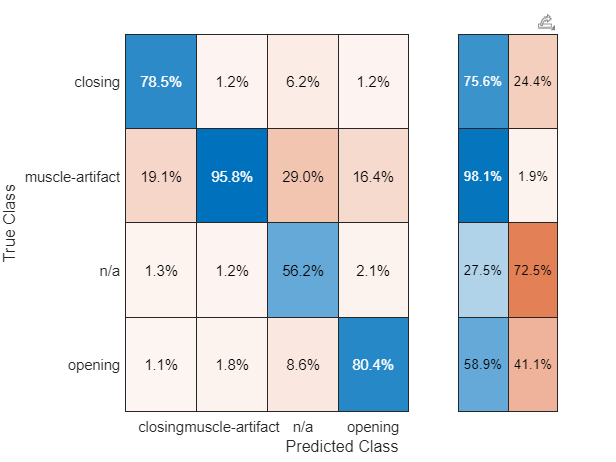

TY = [];
Y = [];
YTest = YTest.';
for k = 1:numel(YTest)
    TY = [TY;YTest{k}];
    Y = [Y;YPred{k}];
end
confusionMat = confusionmat(TY(:),Y(:));
 confusionchart( confusionMat,...
    {'opening' 'closing' 'muscle-artifact' 'n/a'},'Normalization','column-normalized','RowSummary','row-normalized');

OC test

groundTruth = {};
predicted = {};
TP = 0;FP = 0;FN=0;
errorList = [];
for i = 1:numel(Ytest)
    gt = findBlinkFromOpeningClosing(YTest{i});
    p = findBlinkFromOpeningClosing(YPred{i});
    gt = gt{1};p=p{1};
    groundTruth{end+1} = gt;
    predicted{end+1} = p;
    
    TP = TP + numel(intersect(gt,p));
    if (numel(gt) > numel(p))
        FN = FN + numel(gt) - numel(p);
    else
        FP = FP + numel(p) - numel(gt);
    end
    if (numel(gt) ~= numel(p))
        errorList(end+1) = i;
    end        
end 
TP,FP,FN,errorList

TP = 240

FP = 20

FN = 10

errorList =      1    21    23    24    38    39    40    48    69    94    95    96   171   173   175   203   249   255   265   270   271   276   277   292   312   336   405   468


Precision=TP/(TP+FP),Recall=TP/(TP+FN)

Precision = 0.9231

Recall = 0.9600

only blink test

i=1;
[location,timePassed,mask] = detectBlinks(eegTable(:, contains(eegTable.Properties.VariableNames, frontElectrodesLabels)),'modelName','WTCNN',shiftFactor=3,plot=0,output={'location','time','mask'});

Error using signal.internal.filteringfcns.parseAndValidateInputs>extractNameValuePairs
Invalid input parameter name. Valid input names are: 'Steepness' and 'StopbandAttenuation'.

Error in signal.internal.filteringfcns.parseAndValidateInputs (line 81)
opts = extractNameValuePairs(inputCellPvPairs, opts);

Error in 

timePassed

groundTruth = {};
predicted = {};
TP = 0;FP = 0;FN=0;
errorList = [];
for i = 1:numel(Ytest)
    gt = blinkLocate(XTest{i},YTest{i});
    p = blinkLocate(XTest{i},YPred{i});
    groundTruth{end+1} = gt;
    predicted{end+1} = p;
    
    TP = TP + numel(intersect(gt,p));
    if (numel(gt) > numel(p))
        FN = FN + numel(gt) - numel(p);
    else
        FP = FP + numel(p) - numel(gt);
    end
    if (numel(gt) ~= numel(p))
        errorList(end+1) = i;
    end        
end 
TP,FP,FN,errorList
Precision=TP/(TP+FP),Recall=TP/(TP+FN)